## Using ICP Registration of the Incomplete model with original Complete model.

clear all; clc;

kicker_full = csvread("Kicker_complete_Output.xlsx");
kicker_full = pointCloud(kicker_full);

limx = [0 0
        0 0 ];
limy = [min(kicker_full.Location(:,2))-1 max(kicker_full.Location(:,2))-1
        min(kicker_full.Location(:,2))+1 max(kicker_full.Location(:,2))+1 ];
limz = [min(kicker_full.Location(:,3))-1 min(kicker_full.Location(:,3))-1
        max(kicker_full.Location(:,3))+1 max(kicker_full.Location(:,3))+1 ];

gridStep = 1;
points = readtable("Kickerfigur_incomplete.xlsx");
points = points{:,1:3};
points = pointCloud(points);
points_downsampled = pcdownsample(points, "gridAverage", gridStep);





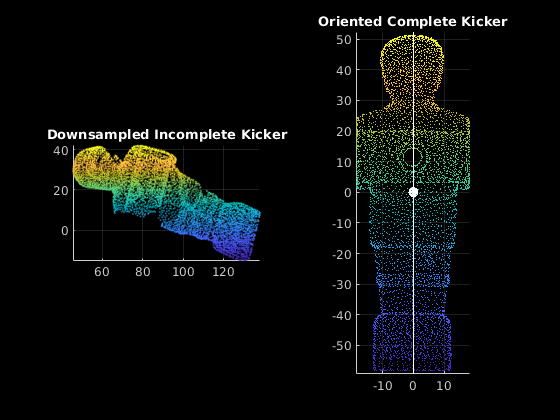



figure(1)
subplot(1,2,1)
pcshow(points_downsampled)
hold on
title("Downsampled Incomplete Kicker")
view([0 0])
hold off

subplot(1,2,2)
pcshow(kicker_full.Location)
title("Oriented Complete Kicker")
hold on
surf(limx, limy, limz, "LineStyle","-", "FaceAlpha",0.25,"EdgeColor",[1,1,1] )
plot3(0, 0, 0,'o','color','w',"MarkerSize",7,'MarkerFaceColor',"white")
hold off
view([0 0])

[tform, movingReg, rmsscore] = pcregistericp(points_downsampled, kicker_full, ...
                "MaxIterations",100, "Tolerance",[0.01, 0.01], "Extrapolate",true);

rmsscore

rmsscore = 0.2174

tform.Translation

ans =   -37.8332  -55.2840   62.5596


tform.Rotation

ans =     0.2433    0.6068   -0.7567
   -0.2394    0.7936    0.5594
    0.9399    0.0451    0.3384


rotMat = tform.Rotation;
theta_x = atan2(rotMat(2,2), rotMat(3,3))*180 / pi

theta_x = 66.9077

theta_y = atan2(-rotMat(3,1), sqrt(rotMat(3,2)^2+ rotMat(3,3)^2))*180 / pi

theta_y = -70.0409

theta_z = atan2(rotMat(2,1), rotMat(1,1))*180 / pi

theta_z = -44.5370

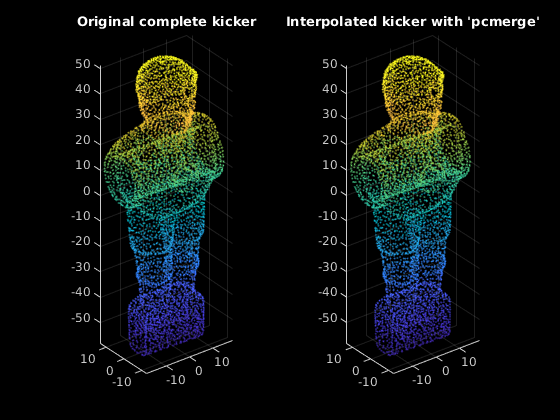

[tform, movingRegistered, rmsscore] = pcregistericp(points_downsampled, kicker_full, "MaxIterations",100, "Tolerance",[0.01, 0.01], "Extrapolate",true);
movingRegistered_ = movingRegistered.Location;
movingRegistered_ = sortrows(movingRegistered_);
subplot(1,2,1)
pcshow(kicker_full)
title("Original complete kicker")

subplot(1,2,2)
pcshow(movingRegistered_)
title("Registered Incomplete Kicker")
subplot(1,2,2)
view([0 0])

newpc = pcmerge(movingReg, kicker_full, gridStep);
pcshow(newpc)
title("Interpolated kicker with 'pcmerge'")

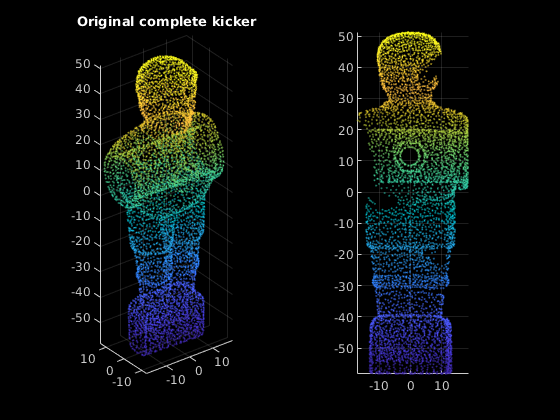

i = 300

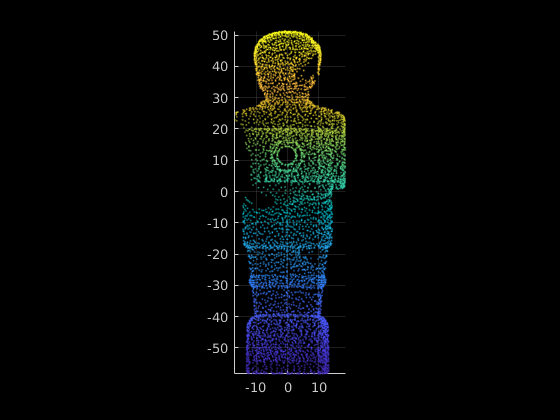

i = 600

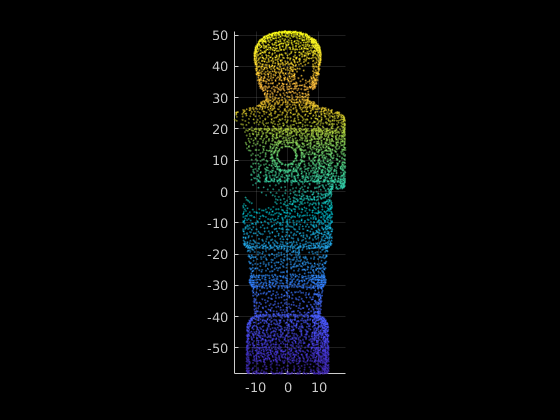

i = 900

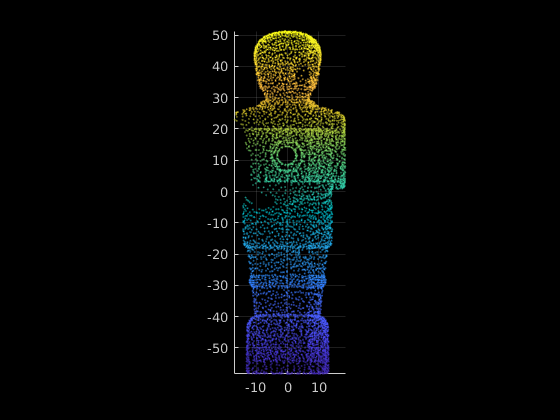

i = 1200

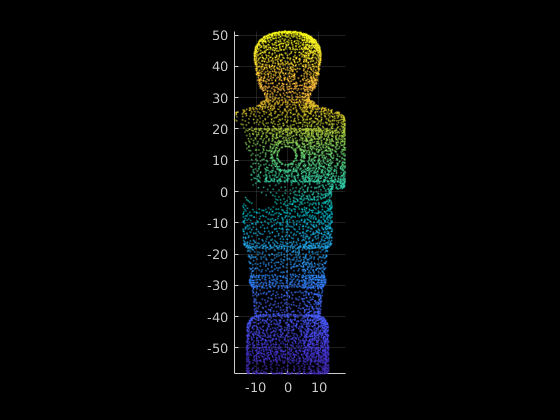

i = 1500

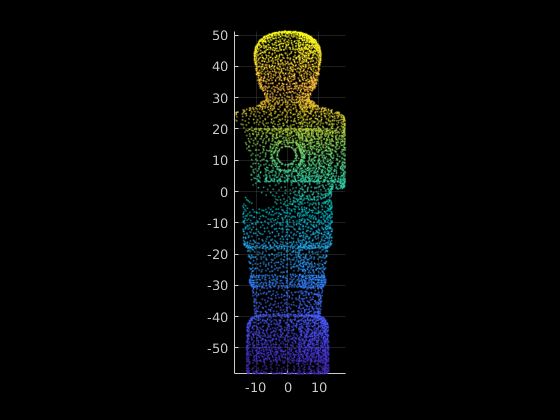

i = 1800

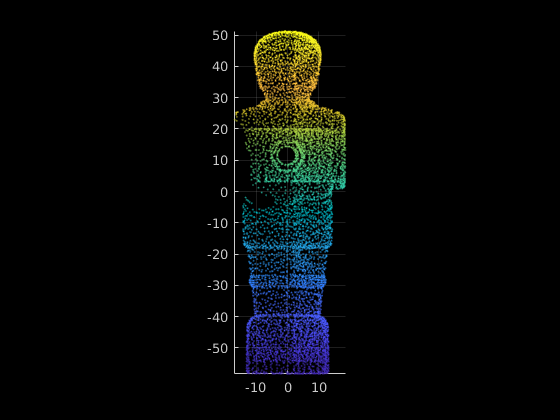

i = 2100

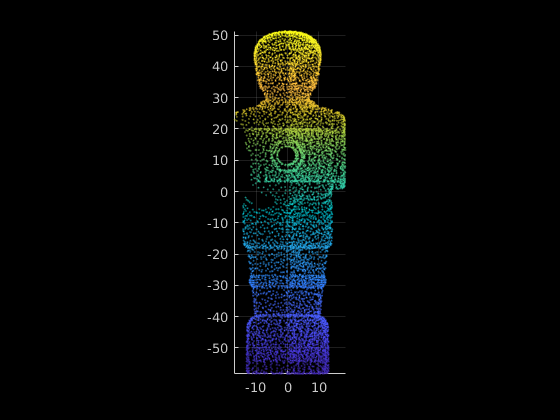

i = 2400

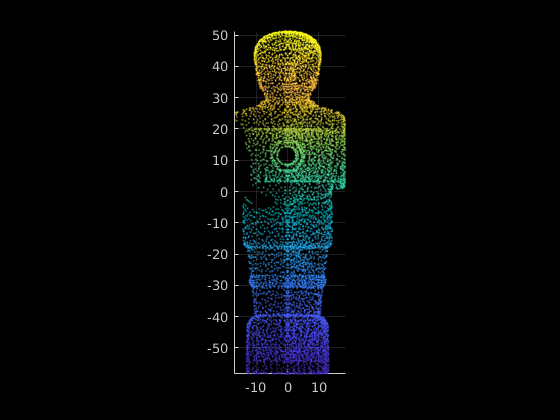

i = 2700

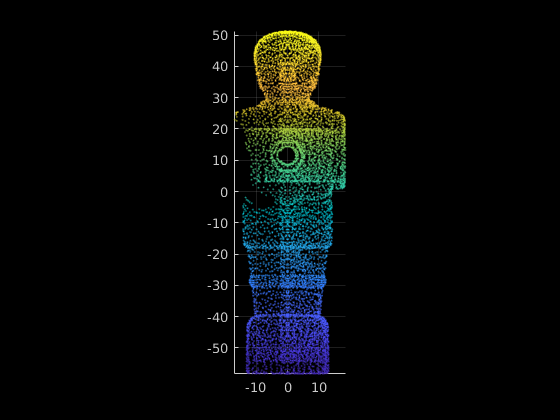

i = 3000

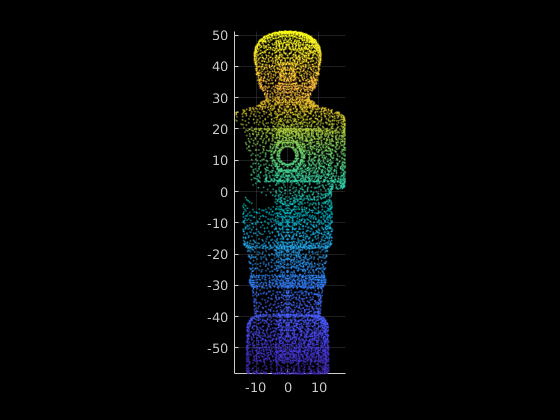

i = 3300

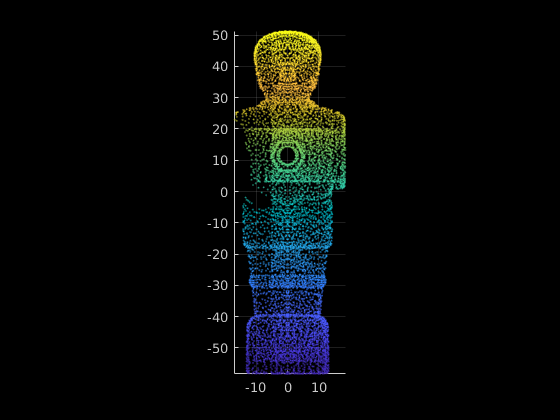

i = 3600

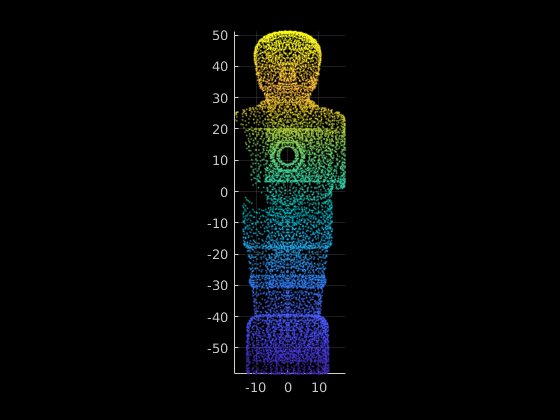

i = 3900

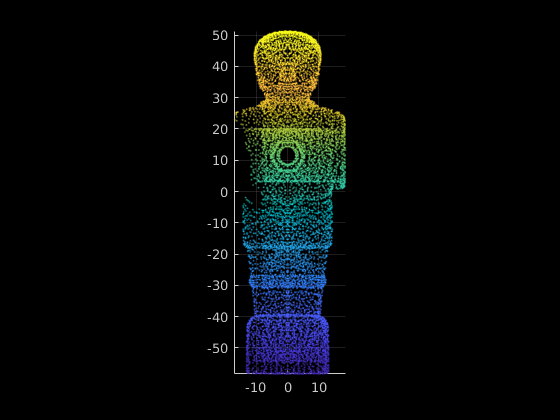

i = 4200

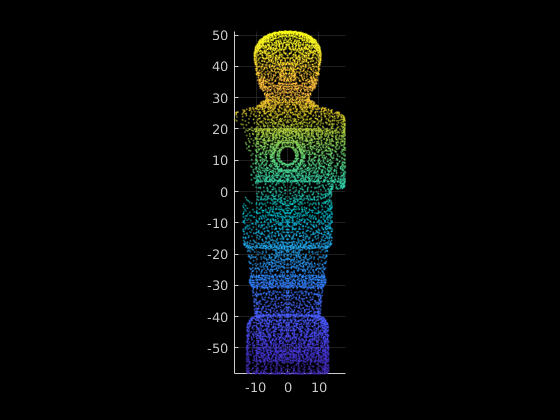

i = 4500

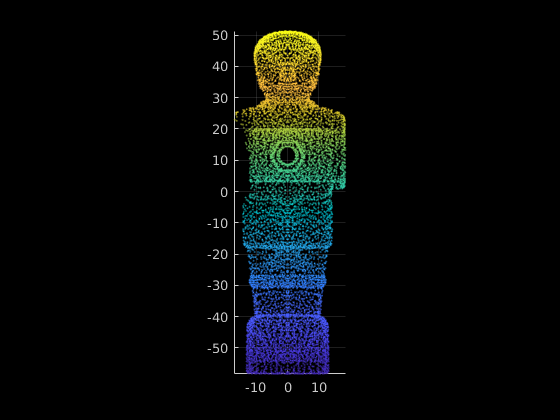

i = 4800

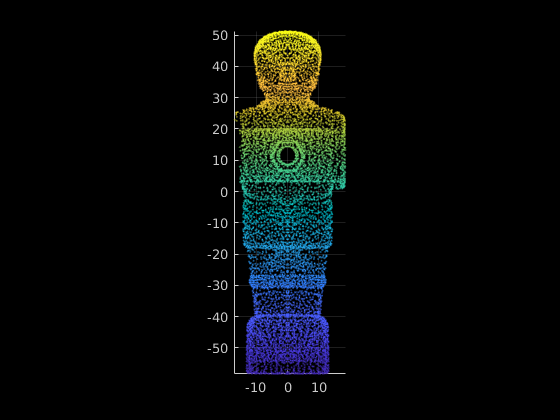

i = 5100

clear ax1; clear ax2;
movingReg = movingRegistered_;
[num_rows, ~] = size(movingReg);

x = 1;
for i = 1:num_rows
    point = movingReg(i,:);
    point(1) = -1*point(1);
    
    movingReg = [movingReg
                    point ];
    if mod(i,300) == 0
        figure(x)
        pcshow(movingReg, "MarkerSize",10)
        hold on
        x = x+1;
        view([0 0])
        i
    end
end

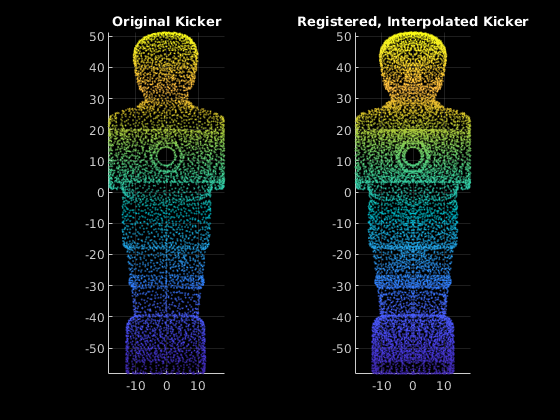



subplot(1,2,1)

pcshow(kicker_full.Location)
title("Original Kicker")

subplot(1,2,2)
pcshow(movingReg)
title("Registered, Interpolated Kicker")

subplot(1,2,2)
view([0 0])

subplot(1,2,1)
view([0 0])